# Filtros

## Importar datos

Importar "S9....mat" de Utils4SP

load("../../Utils4SP/Datasets/S9_Filtros.mat")

%Preproc
atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"])=fillmissing(atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"]),"linear");

## Promedio móvil

- Aplicar promedio móvil a todos los campos de atmósfera

- Comparar series de tiempo antes y después

- Comparar el contenido espectral antes y después del filtro

- Hacer un chart de dispersión y hacer nuevamente un ajuste. Comparar la calidad del ajuste respecto a la práctica de S5.

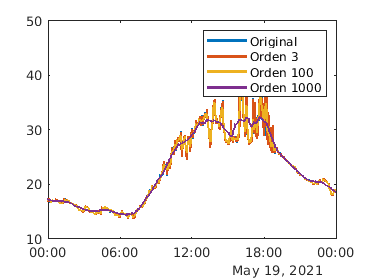

%Promedio móvil 
atmos_movMean_3=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},3);
atmos_movMean_100=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},100);
atmos_movMean_1000=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},1000);

%Visualizar temperatura sin filtro y con filtro
figure
plot(atmosfera.DateTime,[ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],'LineWidth',2)
xlim([datetime(2021,05,19) datetime(2021,05,20)])
legend("Original","Orden 3","Orden 100","Orden 1000" )

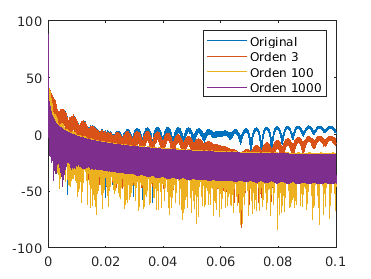


%Contenido espectral
N=numel(atmosfera.Temp_C);
[Pxx,f]=periodogram([ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],[],N*10,1/5);

%Visualización de contenido espectral
figure
plot(f,pow2db(Pxx))
legend("Original","Orden 3","Orden 100","Orden 1000" )

## Detrend

Hacer detrend a las componentes x & y del campo magnético de Cassini con las siguientes técnicas:

- Restando promedio móvil

- Ajustando un polinomio

- Usando detrend

Aplicar el espectrograma a la magnitud de Cassini antes y después del detrend. Observar por qué es importante quitar las bajas frecuencias (Incluido el DC).

## No lineales

Contexto: Los datos de RVB son producto de un sensor altamente inestable y ruidoso.

Hacer la reconstrucción facial de los datos de RVB:

- Remover NaN's

- Usar un filtro no lineal para quitar la mayor cantidad de ruido

- Usar promedio móvil para dar el toque final